# **1D Finite Difference Time Domain Simulation of Maxwell's Equations of Electromagnetism**

`Author: J. Leonardo Yucra | ME 3500`

`Date: 04/13/2025`

### **Description** 

The following script implements a one-dimensional Finite Difference Time Domain (FDTD) simulation of electromagnetic wave behavior in a specified medium. The FDTD method discretizes continuous space-time and converts Maxwell's equations into finite difference form, allowing for numerical solution on a digital computer. 

**Maxwell's Equations**


$$\nabla \times \mathbf{E} = -\frac{\partial \mathbf{B}}{\partial t} \\
\nabla \cdot \mathbf{D} = \rho_{v} \\
\nabla \times \mathbf{H} = \mathbf{J_c} + \frac{\partial \mathbf{D}}{\partial t} \\
\nabla \cdot \mathbf{B} = 0 $$
     
$$\mathbf{D} = [\epsilon] * \mathbf{E}\\
\mathbf{B} = [\mu] * \mathbf{H}\\
$$


A key feature of FDTD simulations is the use of the **Yee Grid**, introduced by Kane S. Yee in 1966 [1]. The Yee algorithm employs a spatial and temporal staggering of electric and magnetic field components within a discretized grid. This structured arrangement satisfies Maxwell's divergence equations, and allows the curl equations to be solved in a leapfrog manner. The approach enhances numerical stability and accuracy in time-domain simulations of electromagnetic wave propagation.  

### Problem Definition

The implementation in this project will simulate electromagnetic propagation through a slab of material. The permeability ($\mu
$) and permitivitty ($\epsilon
$) are material properties defined upon material selection. 

*Choose your material properties and length of the slab:*

clc; clear;
% Constants
c0 = 299792458; %Speed of light
gigahertz = 1e9;
centimeter = 1e-2;

n = 3;
switch n
    case 1
        er = 3.8;
        ur = 1.95;
    case 2
        er = 2.1;
        ur = 1.45;
    case 3
        er = 2.25;
        ur = 1.5;
end

d = 30.4*centimeter;

In addition, to simplify the complexity of the problem, the following **assumptions** are made:

- Material properties are linear, isotropic, and non-dispersive

- Refractive index is the same at both boundaries.

- Waves at boundaries on  ly travel outward.

 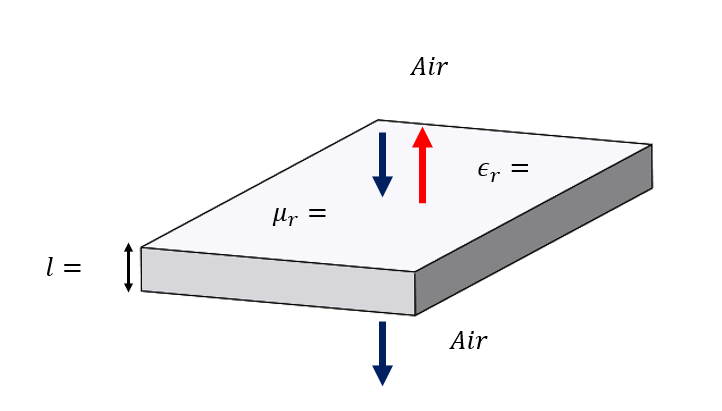

Fig 1: Diagram of Problem Setup

### Grid Layout

Given the assumptions, a discretized grid needs to be constructed with N amount of cells. The grid is divided in a total-field and scattered field in order to inject a one-way source, there will be spacer regions between the reflection and transmission points. The wave will be evaluated at each point of the grid and behave accordingly.

*Choose the parameters for the grid resolution*

% Grid Wavelength Criteria

fmax = 1*gigahertz;

NTFSF = 3; %Scatter field cells

Nlambda = 20;
nmax = sqrt(ur*er);
lambdamin = c0/fmax/nmax;
dlambda = lambdamin/Nlambda;

% Grid Structure Criteria
Nd = 4;
deld = d/Nd;

% Grid Resolution
dz = min(dlambda,deld);
Nc = ceil(d/dz);
free_region = 10;
N = Nc + 2*free_region + NTFSF;

                  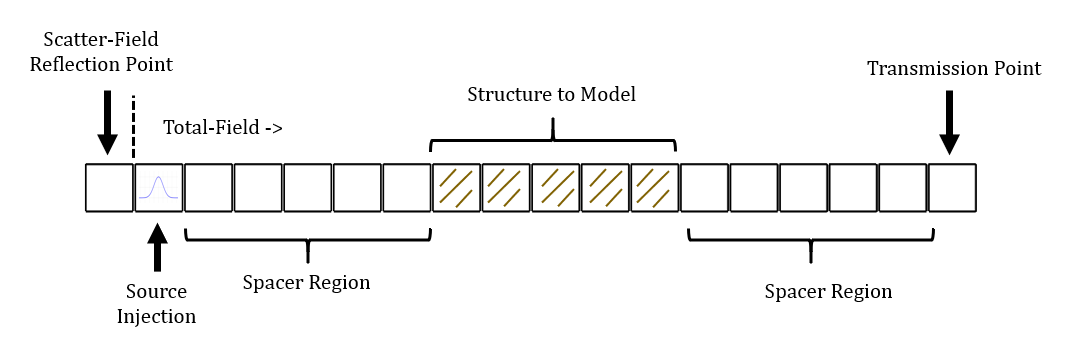

Fig 2: Grid layout for Specific Regions

% Apply material properties at specific cells
nz1 = NTFSF + free_region;
nz2 = nz1 + ceil(d/dz) - 1;
UR(nz1:nz2) = ur;
ER(nz1:nz2) = er;

% Time step
nbc = 1; %Refractive index due to air
dt = nbc*dz/(2*c0);

%Source parameters
B = gigahertz;
tau = 1/(2*B);
t0 = 6*tau;
tprop = nmax*N*dz/c0; % time steps
T = 12*tau + 5*tprop;
STEPS = ceil(T/dt); % Iterations for time steps 

### Gaussian Pulse

A short "one-way" Gaussian pulse is injected into the grid. The Gausian pulse contains a broad spectrum of frequencies centered around a peak frequency, which makes it ideal for testing the system across a wide range of frequencies and characterizing frequency-dependent behavior.

%Definition of source functions
nsrc = 1; ersrc = 1; ursrc = 1;
t = (0:STEPS-1)*dt;
delt = nsrc*dz/(2*c0) + dt/2;
A = -sqrt(ersrc/ursrc); %permittivity and permeability before material --->Change 
Esrc = exp(-((t-t0)/tau).^2);
Hsrc = A*exp(-((t-t0+delt)/tau).^2);

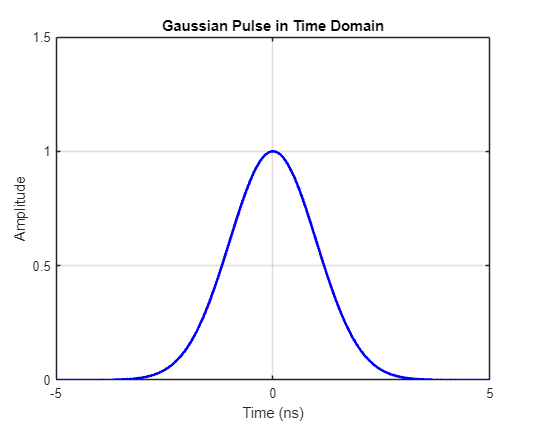

Fig 3: Gaussian Source injected into the system

Additionally, it is beneficial to perform a Fourier Transform of the traveling wave in order to calculate the **reflectance** and **transmittance** of the system. By comparing the frequency spectra of the incident, reflected, and transmitted fields—typically measured at observation points before and after a material interface or structure,  the frequency-dependent reflection (R) and transmission (T) coefficients can be determined

%Fourier Transform
NFREQ = 100;
FREQ = linspace(0,1*gigahertz,NFREQ);
K = exp(-1i*2*pi*dt*FREQ);
%Arrays for reflectance and transmittance
REF = zeros(1,NFREQ);
TRN = zeros(1,NFREQ);
SRC = zeros(1,NFREQ);


$$K_n  = e^{-j2\pi f_n \Delta t} $$


### Finite Difference Algorithm